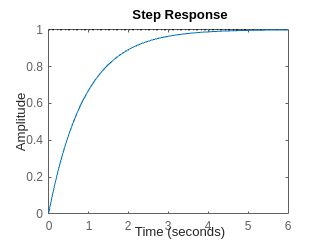

s = tf('s');
G = 5/s;
lambda = 0.9;
C = 1/(5*lambda);
M = feedback(C*G,1);
step(M)

outro treste

s = tf('s');
k = 1;
tau = 1;

tau = 1

G = k/(tau*s+1);
z = 0.7;
ts = 4;
wn = 4/(z*ts)

wn = 1.4286

kp = (2*z*wn*tau - 1)/k

kp = 1

ti = (2*z*wn*tau - 1)/(tau*wn^2)

ti = 0.4900

c_i = kp/(ti*s)

c_i =
 
    1
  ------
  0.49 s
 
Continuous-time transfer function.
Model Properties


C2 = kp + c_i 

C2 =
 
  0.49 s + 1
  ----------
    0.49 s
 
Continuous-time transfer function.
Model Properties


m = feedback(G*C2,1)

m =
 
       0.49 s + 1
  ---------------------
  0.49 s^2 + 0.98 s + 1
 
Continuous-time transfer function.
Model Properties


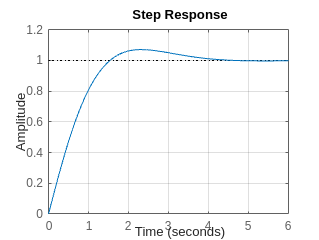

step(m); grid;

a = stepinfo(m)

a = struct with fields:
         RiseTime: 1.1060
    TransientTime: 3.6982
     SettlingTime: 3.6982
      SettlingMin: 0.9141
      SettlingMax: 1.0702
        Overshoot: 7.0208
       Undershoot: 0
             Peak: 1.0702
         PeakTime: 2.3026


mp = exp(-pi*z/(sqrt(1-z^2)))*100

mp = 4.5988

tau_1 = 10;
tau_2 = 2;
teta = 2;
k = 10;
G = k*exp(-2*s)/((tau_1*s + 1)*(tau_2*s+1))

G =
 
                     10
  exp(-2*s) * -----------------
              20 s^2 + 12 s + 1
 
Continuous-time transfer function.
Model Properties


G_pade = pade(G)

G_pade =
 
          -10 s + 10
  --------------------------
  20 s^3 + 32 s^2 + 13 s + 1
 
Continuous-time transfer function.
Model Properties


lambda = 1;
ti = tau_1 + tau_2

ti = 12

td = tau_1*tau_2/ti

td = 1.6667

kp = ti/(k*(lambda+teta))

kp = 0.4000

c_d = td*s

c_d =
 
  1.667 s
 
Continuous-time transfer function.
Model Properties


c_i = 1/(ti*s)

c_i =
 
   1
  ----
  12 s
 
Continuous-time transfer function.
Model Properties


C = kp + kp*c_d  + kp*c_i

C =
 
  8 s^2 + 4.8 s + 0.4
  -------------------
         12 s
 
Continuous-time transfer function.
Model Properties


m = feedback(G*C,1);

m =
 
  A = 
             x1        x2        x3
   x1   -0.9333     -0.25  -0.01667
   x2         1         0         0
   x3         0         1         0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
            x1       x2       x3
   y1   0.3333      0.2  0.01667
 
  D = 
       u1
   y1   0
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 2 
 
Continuous-time state-space model.


m_pade = feedback(G_pade*C,1)

m_pade =
 
       -80 s^3 + 32 s^2 + 44 s + 4
  --------------------------------------
  240 s^4 + 304 s^3 + 188 s^2 + 56 s + 4
 
Continuous-time transfer function.
Model Properties


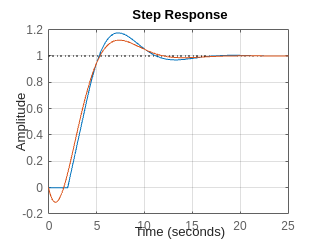

step(m,m_pade); grid;